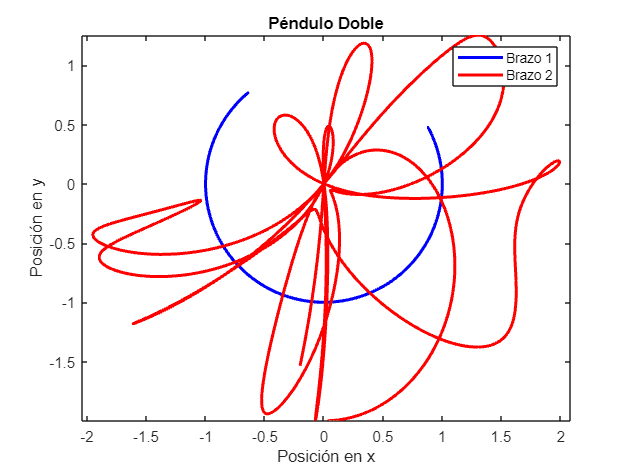


    % Parámetros del péndulo doble
    g = 9.81;       % Aceleración debida a la gravedad (m/s^2)
    L1 = 1.0;       % Longitud del primer brazo del péndulo (metros)
    L2 = 1.0;       % Longitud del segundo brazo del péndulo (metros)
    
    % Condiciones iniciales
    theta1_0 = 0;  % Ángulo inicial del primer brazo (en radianes)
    theta2_0 = pi/100;   % Ángulo inicial del segundo brazo (en radianes)
    omega1_0 = 0;            % Velocidad angular inicial del primer brazo (rad/s)
    omega2_0 = 0;            % Velocidad angular inicial del segundo brazo (rad/s)
    
    % Tiempo de simulación
    tspan = [0, 10];  % Intervalo de tiempo de simulación (segundos)
    
    % Condiciones iniciales y parámetros del sistema en un vector
    initial_conditions = [theta1_0, omega1_0, theta2_0, omega2_0];
    
    % Resolución de las ecuaciones diferenciales
    options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);
    [t, y] = ode45(@(t, y) double_pendulum_ode(t, y, g, L1, L2), tspan, initial_conditions, options);
    
    % Extraer los ángulos de los brazos
    theta1 = y(:, 1);
    theta2 = y(:, 3);
    
    % Gráfica de las trayectorias
    figure;
    plot(L1*sin(theta1), -L1*cos(theta1), 'b', 'LineWidth', 2);
    hold on;
    plot(L1*sin(theta1) + L2*sin(theta2), -(L1*cos(theta1) + L2*cos(theta2)), 'r', 'LineWidth', 2);
    axis equal;
    xlabel('Posición en x');
    ylabel('Posición en y');
    title('Péndulo Doble');
    legend('Brazo 1', 'Brazo 2');

function dydt = double_pendulum_ode(t, y, g, L1, L2)
    % Ecuaciones diferenciales para el péndulo doble
    theta1 = y(1);
    omega1 = y(2);
    theta2 = y(3);
    omega2 = y(4);
    
    % Derivadas de los ángulos
    dydt = [omega1;
            (-g * (2 * sin(theta1) + sin(theta2) * cos(theta1 - theta2)) - omega2^2 * L2 * sin(theta1 - theta2) -omega1^2 * L1 * sin(theta1 - theta2) * cos(theta1 - theta2)) /(L1 * (2 - cos(2 * (theta1 - theta2))));
            omega2;
            (2 * g * sin(theta1 + cos(theta1 - theta2)) + ...
             omega1^2 * L1 * sin(theta1 - theta2) + ...
             omega2^2 * L2 * sin(theta1 - theta2) * cos(theta1 - theta2)) / ...
            (L2 * (2 - cos(2 * (theta1 - theta2))))];
end
